clear

addpath("matlab_functions\")

method = "Analytical";

#### Compute Sensitivity

if strcmpi(method, 'Analytical')
    [Plate, Coil, Sensor] = myModel;
else
    [Plate, Coil, Sensor, Model] = myModel;
    mesh_size = 2; % 1:finest 9:coarsest
end

for freq = 100%[900 225 100 55]
    if strcmpi(method, 'Analytical')
        S = ComputeSensitivityAnalytical(Plate, Coil, Sensor, freq);
    else
        S = ComputeSensitivityFEM(Model, Plate, Coil, Sensor, freq, mesh_size);
    end
    
    element_centers = Plate.elems_center;
    
    fname = sprintf('data/Sensitivity_%dHz_%s.mat', freq, datetime('now','Format','MMdd-HHmm'));
    save(fname, 'S','element_centers')
end

clear method mesh_size freq fname element_centers

#### Visualize Sensitivity

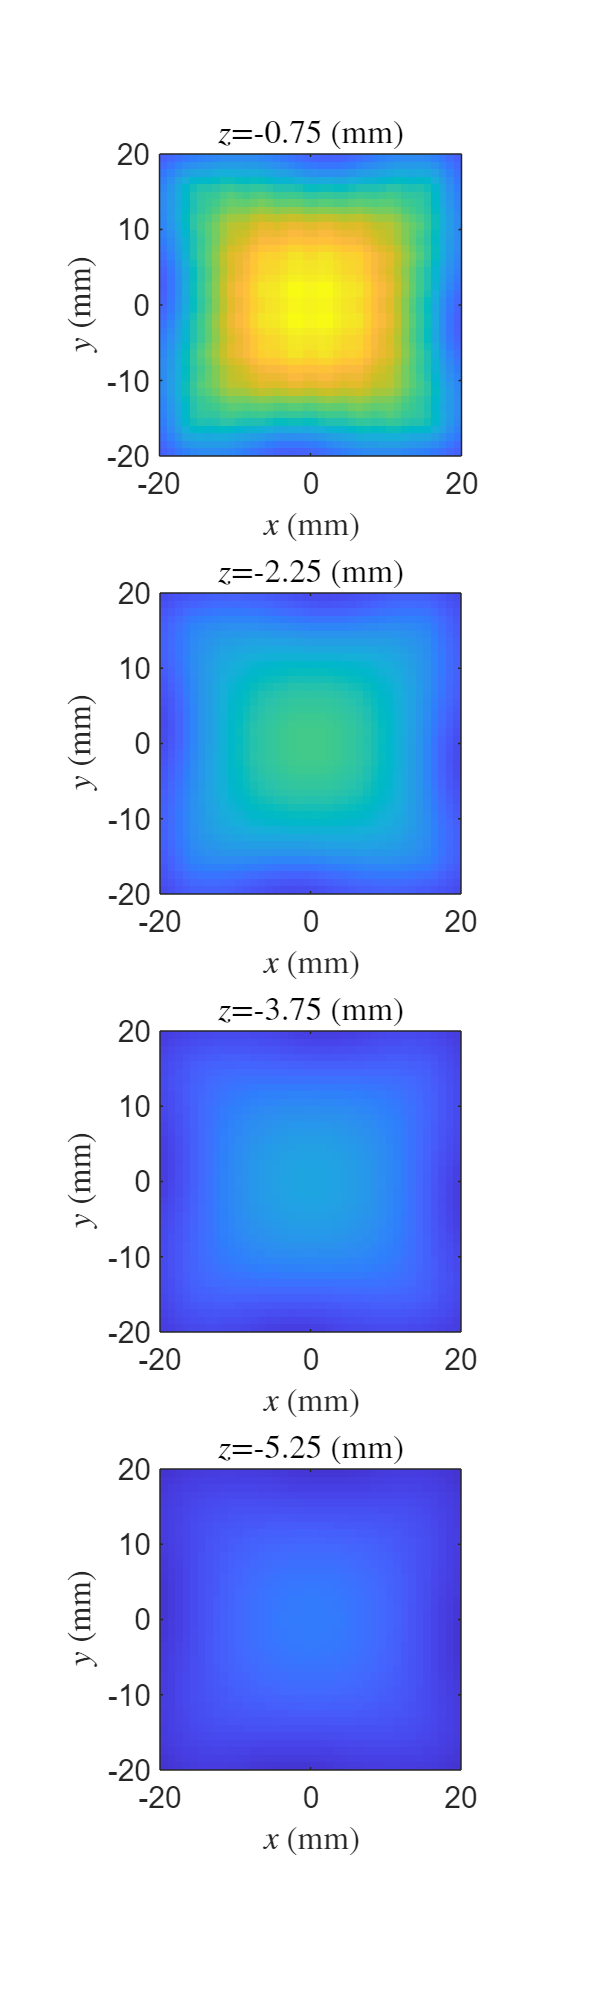

load('data\Sensitivity_100Hz_temp.mat')
VisualizeSensitivity(S, element_centers, 'all')

function S = ComputeSensitivityFEM(Model, Plate, Coil, Sensor, freq, mesh_size)

S = zeros(size(Sensor.positions,2), size(Plate.gauss_points,3));

tic
ComsolModel('SolveCoil', Model, Coil, freq, mesh_size);
E1 = ComsolModel('InterpField', Model, 'E', Plate.gauss_points);
fprintf('Compute coil took %.2f seconds\n', toc)

for i = 1:size(Sensor.positions,2)
    Sensor.compute_index = i;

    tic
    ComsolModel('SolveSensor', Model, Sensor, freq, mesh_size);
    E2 = ComsolModel('InterpField', Model, 'E', Plate.gauss_points);
    fprintf('Compute sensor %d took %.2f seconds\n', i, toc)
    
    S(i,:) = sum(dot(E1,E2) .* Plate.gauss_weights, 2);    
end

end

function S = ComputeSensitivityAnalytical(Plate, Coil, Sensor, freq)

x = Plate.gauss_points(1,:,:);
y = Plate.gauss_points(2,:,:);
z = Plate.gauss_points(3,:,:);
omega = 2*pi * freq;

S = zeros(size(Sensor.positions,2), size(Plate.gauss_points,3));

tic
[E1x,E1y] = CoilElectricField(Coil, Plate, x, y, z, omega);
fprintf('Compute coil took %.2f seconds\n', toc)

for i = 1:size(Sensor.positions,2)
    Sensor.compute_index = i;

    tic
    [E2x,E2y] = SensorElectricField(Sensor, Plate, x, y, z, omega);
    fprintf('Compute sensor %d took %.2f seconds\n', i, toc)
    
    S(i,:) = sum((E1x.*E2x + E1y.*E2y) .* Plate.gauss_weights, 2);    
end

end

function [Ex,Ey] = CoilElectricField(Coil, Plate, x,y,z, omega)

if Coil.fillet ~= Coil.width / 2
    error('Only support cylindrical coil')
end
zc = unique(Coil.positions(3,:));
if numel(zc) ~= 1
    error('Coils must be at the same z position')
end
r2 = Coil.width / 2;
r1 = r2 - Coil.thickness;
z2 = zc + Coil.height / 2;
z1 = zc - Coil.height / 2;
N = Coil.N_turns;
sigma = Plate.conductivity;
mur   = Plate.relative_permeability;
d     = Plate.height;    
coilAbovePlate = CoilAbovePlate(r1,r2,z1,z2,N, sigma,mur,d);

Ex = 0;
Ey = 0;
for k = 1:size(Coil.positions,2)
    [theta,r] = cart2pol(x-Coil.positions(1,k), y-Coil.positions(2,k));
    E_theta = coilAbovePlate.E(r,z,omega) * Coil.current(k);
    Ex = Ex + E_theta .* -sin(theta);
    Ey = Ey + E_theta .*  cos(theta);
end

end

function [Ex,Ey] = SensorElectricField(Sensor, Plate, x,y,z, omega)

sigma = Plate.conductivity;
mur   = Plate.relative_permeability;
d     = Plate.height;

k = Sensor.compute_index;
sensorAbovePlate = SensorAbovePlate(Sensor.positions(3,k), Sensor.axes(:,k), sigma,mur,d);

[Ex,Ey] = sensorAbovePlate.E(x-Sensor.positions(1,k), y-Sensor.positions(2,k), z, omega);

end

function VisualizeSensitivity(S, element_centers, varargin)

z = unique(element_centers(3,:));
z = sort(z, 'descend');

scale = 1e3;

if isempty(varargin) || strcmpi(varargin{1}, 'all')
    S_norm = vecnorm(S);
else
    S_norm = abs(S(varargin{1},:));
end

figure('Position',[10 10 300 250*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c = reshape(S_norm(mask), sqrt(sum(mask)),[]);

    x = [min(element_centers(1,mask)) max(element_centers(1,mask))] * scale;
    y = [min(element_centers(2,mask)) max(element_centers(2,mask))] * scale;

    subplot(length(z),1,k)
    imagesc(x, y, c.', [0 max(S_norm)])
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end

end